% Define the file name and open the file for reading
filename = 'ESP-Now_2_0.01.txt';


% Read the LTSpice data as a table
data = readtable(filename, 'Delimiter', ','); % Assuming tab-delimited data

Error using readtable
Unable to find or open
'ESP-Now_2_0.01.txt'. Check the path and
filename or file permissions.


time_diff = zeros(size(data.time));
for c = 1:size(data.time)
    if data.newtime(c)- data.time(c)  < 0
        time_diff(c) = 1000+( data.newtime(c) - data.time(c));
    else
        time_diff(c) = data.newtime(c) - data.time(c);
    end
end
time_diff
% 
% rssi = zeros(1000,1);
% i = 1;
% for c = 1:size(data.rssi)
%     if (-60 < data.rssi(c))
%         rssi(c) = data.rssi(c);
%     end
% end
% sum(nonzeros(rssi))/numel(nonzeros(rssi))

loss = zeros(size(data.s));
for c = 1:size(data.s)
    loss(c) = data.s(c) - data.l(c);
end
loss


figure;

x = (linspace(0,0.1*(numel(time_diff)-1),numel(time_diff)))'
subplot(2,1,1);
plot(time_diff);
title("Response Time(ms) Per Packet Returned During Short Term Heavy Load (100msgs/s")
xlabel('Number of Packets Returned');
ylabel('Response Time (ms)');
xlim([0 1000])
grid on
grid minor
yline(sum(time_diff)/numberofelements(time_diff))
sum(time_diff)/numberofelements(time_diff)

subplot(2,1,2);
histogram(time_diff,'NumBins',50)
title("Histogram Showing the Distribution of Response Times(ms)")
ylabel('Number of Packets Returned');
xlabel('Response Time (ms)');
xline(sum(time_diff)/numberofelements(time_diff))
max(time_diff)

set(gcf, 'PaperUnits', 'centimeters');
set(gcf, 'PaperPosition', [0 0 10 15]); %x_width=10cm y_width=15cm
saveas(gcf,'fig1.tif')

% Define the file name and open the file for reading
filename = 'ESP-Now_1_0.05.txt';


% Read the LTSpice data as a table
data = readtable(filename, 'Delimiter', ','); % Assuming tab-delimited data

time_diff = zeros(1,1000);
for c = 1:size(data.time)
    if data.newtime(c)- data.time(c)  < 0
        time_diff(c) = 1000+( data.newtime(c) - data.time(c));
    else
        time_diff(c) = data.newtime(c) - data.time(c);
    end
end
time_diff

time_diff =     15    13    14    13    14    13    14    14    13    14    14    14    14    14    14    14    14    14    14    14    14    14    14    15    14    14    14    15    14    14    14    14    14    14    14    14    14    14    14    14    14    14    14    14    14    14    14    14    14    14


% 
% rssi = zeros(1000,1);
% i = 1;
% for c = 1:size(data.rssi)
%     if (-60 < data.rssi(c))
%         rssi(c) = data.rssi(c);
%     end
% end
% sum(nonzeros(rssi))/numel(nonzeros(rssi))

loss = zeros(size(data.s));
for c = 1:size(data.s)
    loss(c) = data.s(c) - data.l(c);
end
loss

loss =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0




figure;

x = (linspace(0,0.1*(numel(time_diff)-1),numel(time_diff)))'

x =          0
    0.1000
    0.2000
    0.3000
    0.4000
    0.5000
    0.6000
    0.7000
    0.8000
    0.9000


subplot(2,1,1);
plot(time_diff);
title("ESP-Now: Response Time(ms) Per Packet Returned During Short Term Heavy Load")
xlabel('Number of Packets Returned');
ylabel('Response Time (ms)');
%xlim([0 350])
grid on
grid minor
yline(sum(time_diff)/numberofelements(time_diff))
sum(time_diff)/numberofelements(time_diff)

ans = 14.4497

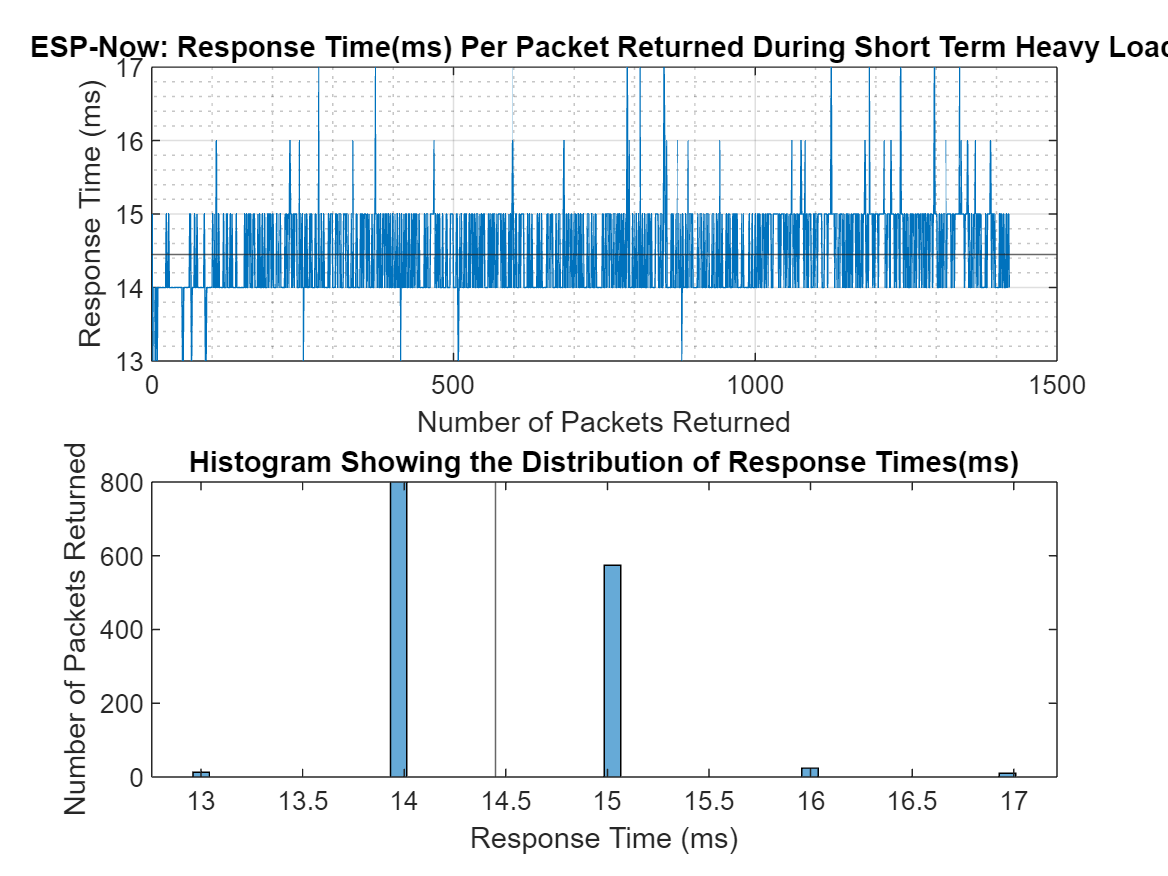


subplot(2,1,2);
histogram(time_diff,'NumBins',50)
title("Histogram Showing the Distribution of Response Times(ms)")
ylabel('Number of Packets Returned');
xlabel('Response Time (ms)');
xline(sum(time_diff)/numberofelements(time_diff))

max(time_diff)

ans = 17

% Define the file name and open the file for reading
filename = 'ESP_NOW_24Oct4.txt';


% Read the LTSpice data as a table
data = readtable(filename, 'Delimiter', ','); % Assuming tab-delimited data

Error using readtable
Unable to find or open
'ESP_NOW_24Oct4.txt'. Check the path and
filename or file permissions.


time_diff = zeros(1,1000);
for c = 1:size(data.time)
    if data.newtime(c)- data.time(c)  < 0
        time_diff(c) = 1000+( data.newtime(c) - data.time(c));
    else
        time_diff(c) = data.newtime(c) - data.time(c);
    end
end
time_diff
% 
% rssi = zeros(1000,1);
% i = 1;
% for c = 1:size(data.rssi)
%     if (-60 < data.rssi(c))
%         rssi(c) = data.rssi(c);
%     end
% end
% sum(nonzeros(rssi))/numel(nonzeros(rssi))

loss = zeros(size(data.s));
for c = 1:size(data.s)
    loss(c) = data.s(c) - data.l(c);
end
loss


figure;

x = (linspace(0,0.1*(numel(time_diff)-1),numel(time_diff)))'
subplot(2,1,1);
plot(time_diff);
title("ESP-Now: Response Time(ms) Per Packet Returned During Short Term Heavy Load (100msgs/s)")
xlabel('Number of Packets Returned');
ylabel('Response Time (ms)');
xlim([3 1000])
grid on
grid minor
yline(sum(time_diff)/numberofelements(time_diff))
sum(time_diff)/numberofelements(time_diff)

subplot(2,1,2);
histogram(time_diff,'NumBins',50)
title("Histogram Showing the Distribution of Response Times(ms)")
ylabel('Number of Packets Returned');
xlabel('Response Time (ms)');
xline(sum(time_diff)/numberofelements(time_diff))
max(time_diff)
